**Task 1:**

See how we can create a signal named “Constant” with 10 values (= samples) where all

samples have the same value 1. The signal is displayed in a figure.

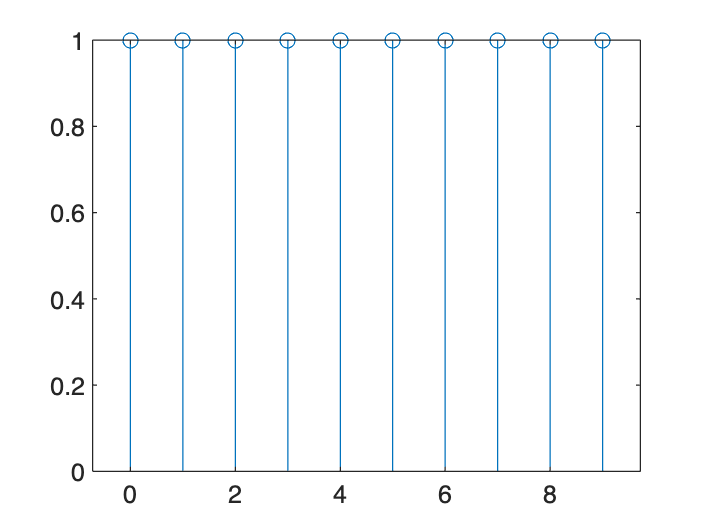

Constant = ones(1, 10);
figure;
stem(0:9, Constant)

Let´s create a ramp signal named “Ramp” with the values 1,2,3,4,5,6,7,8,9,10. Plot the signal

in the same figure as the signal before, but in a separate sub-window.

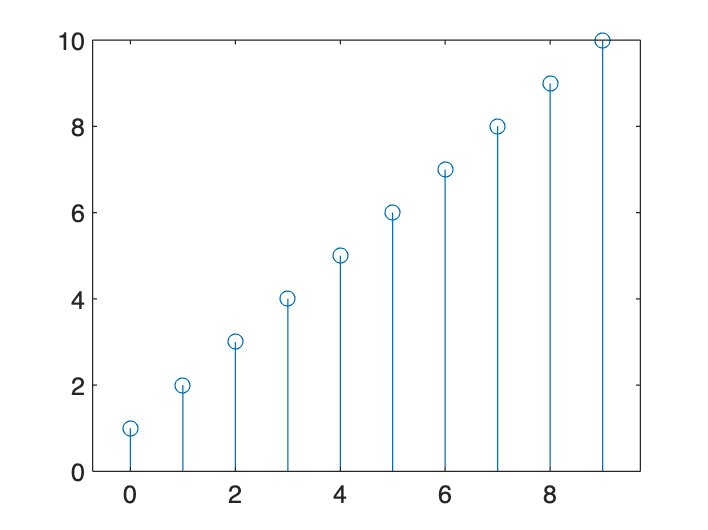

Ramp = 1:1:10;
figure;
stem(0:9, Ramp)

Let´s create a new signal called ConstantRamp that consists of the “Constant” followed by the

“Ramp” signals created above.

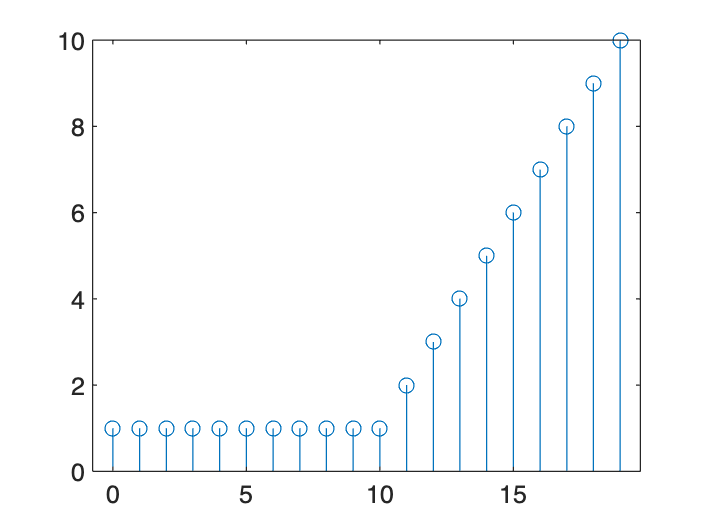

ConstantRamp = [Constant, Ramp];
figure;
stem(0:length(ConstantRamp) - 1, ConstantRamp)

Read values of the signal “ConstantRamp” in positions 0, 5 and 13.

Also read and display the values from position 8 to 14.

ConstantRamp(1)

ans = 1

ConstantRamp(6)

ans = 1

ConstantRamp(14)

ans = 4

ConstantRamp(9:15)

ans =      1     1     1     2     3     4     5


**Task 1.1:**

*Create a "double-ramp" signal called DoubleRamp with values:*

*0,1,2,3,4,5,6,7,8,9,10,9,8,7,6,5,4,3,2,1,0*

DoubleRamp = [0:1:10, 9:-1:0];
DoubleRamp

DoubleRamp =      0     1     2     3     4     5     6     7     8     9    10     9     8     7     6     5     4     3     2     1     0


*Create a new signal called NewRamp from the signal DoubleRamp using indexing.*

*NewRamp should have values 7,8,9,10,9,8,7.*

NewRamp = DoubleRamp(8:14);
NewRamp

NewRamp =      7     8     9    10     9     8     7


*Plot the two signals in the same figure.*

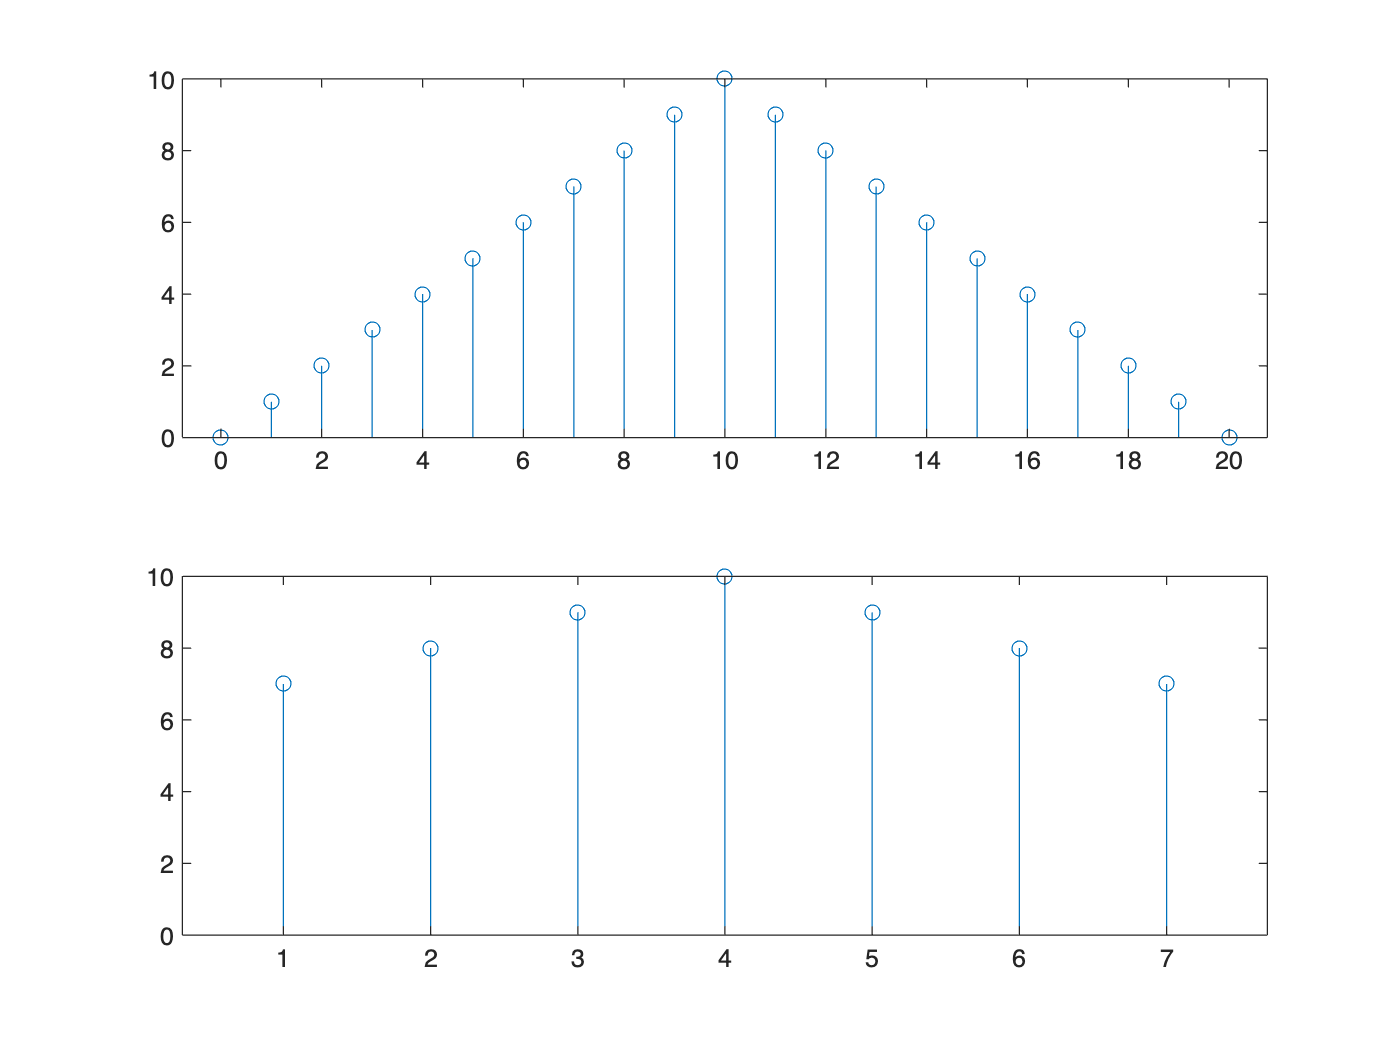

figure;
subplot(2,1,1);
stem(0:length(DoubleRamp) - 1, DoubleRamp);
subplot(2,1,2);
stem(NewRamp);

**Task 2:**

Create a cosine signal with a length of 200 samples named “Cos1”, with amplitude = 1,

frequency = 200 Hz, phase angle nf = 0, which is sampled with a sampling frequency of 10

kHz. The signal is periodic with period N = 50

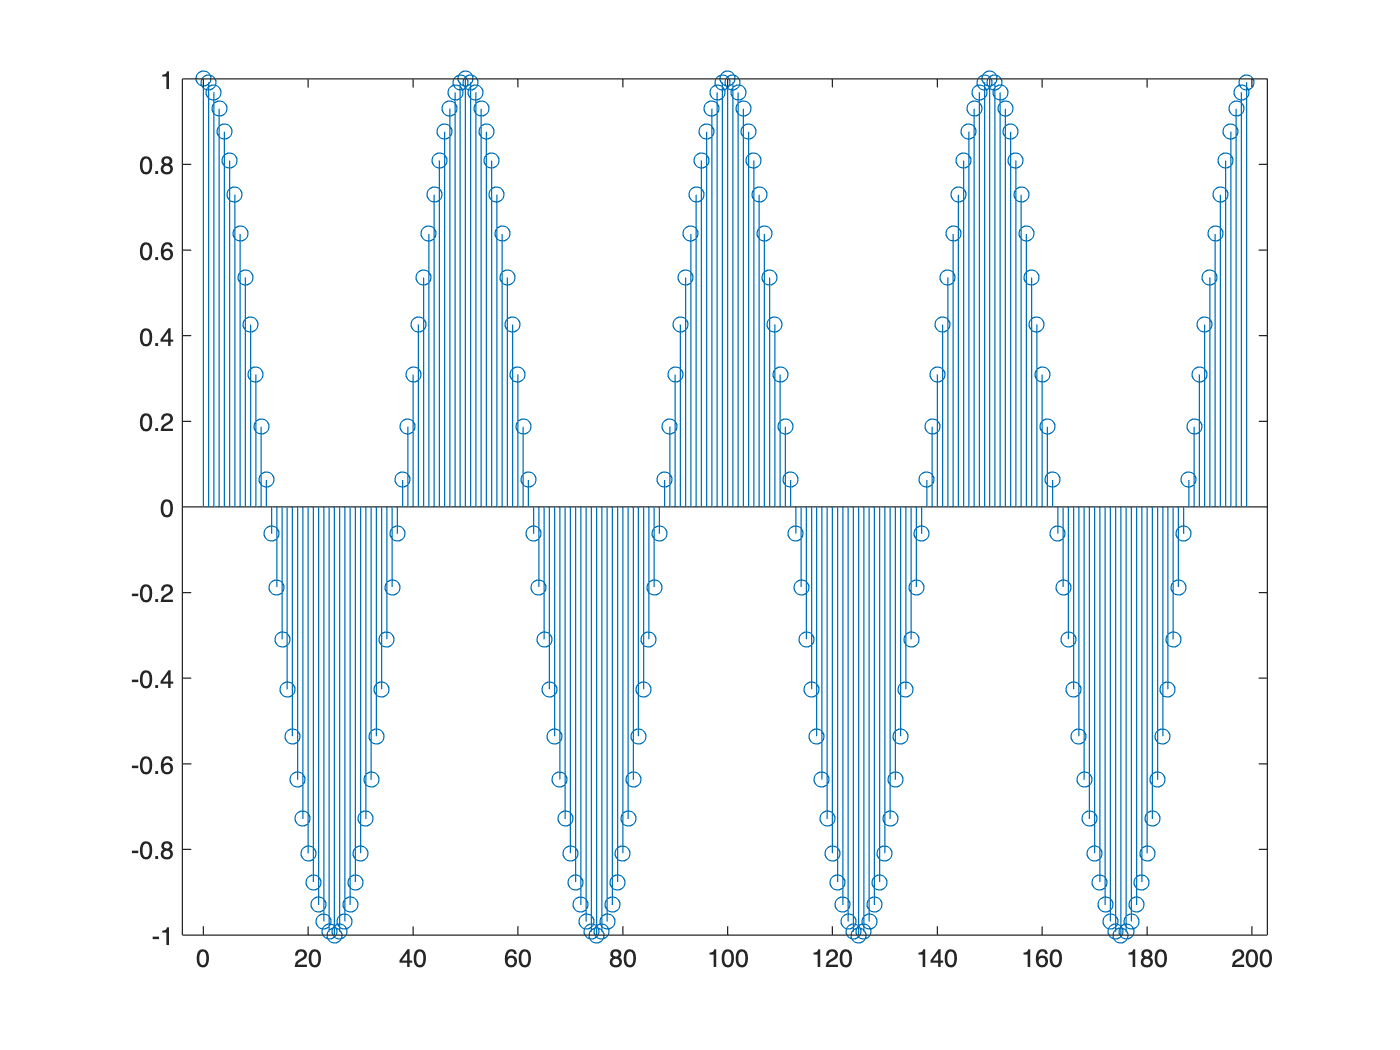

A = 1;
f = 200;
fs = 10000;
nf = 0;
x = 0:199;
signal = A * cos(2 * pi * (f / fs) * (x + nf));

figure;
subplot(3,1,1);
stem(x, signal);

**Task 2.1:**

*Changing frequency of the cosine signal.*

*Halve the frequency to f = 100 Hz and plot with subplot (3,1,2) in Figure 2.*

*Double the frequency f = 400 Hz and plot with subplot (3,1,3) in Figure 2.*

*How does the appearance of the cosine signal change when decreasing or increasing the*

*frequency?*

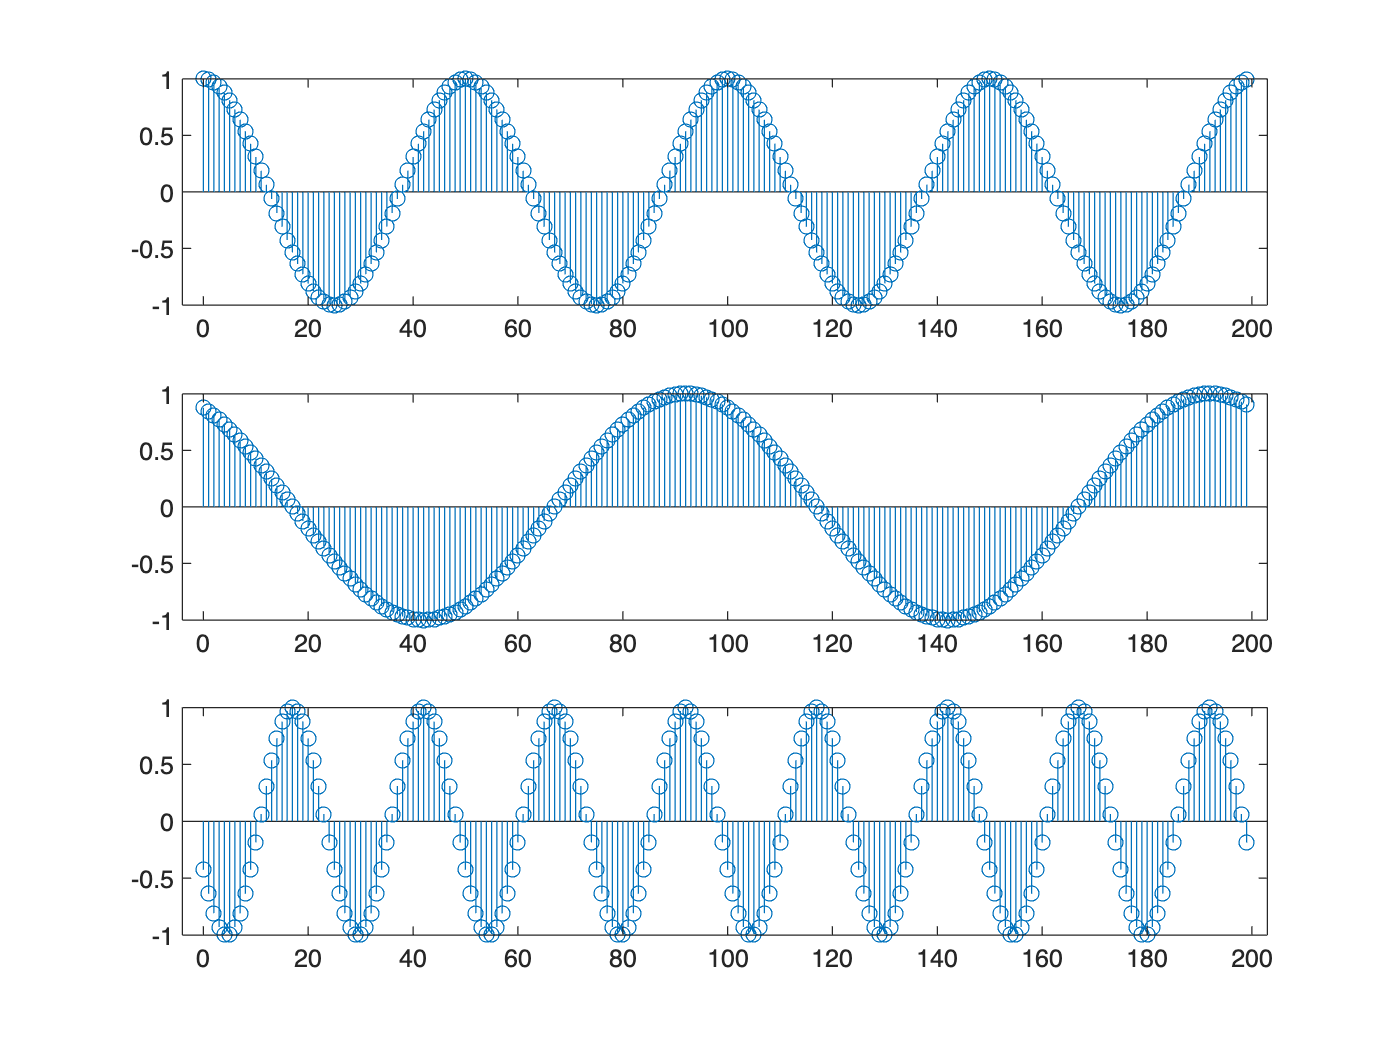

f = 100;
signal_100 = A * cos(2 * pi * (f / fs) * (x + nf));
subplot(3,1,2);
stem(x, signal_100);
f = 400;
signal_400 = A * cos(2 * pi * (f / fs) * (x + nf));
subplot(3,1,3);
stem(x, signal_400);

*Now change the phase angle nf.*

*Plot the cosine signal with phase angle nf = 0 in figure 21 with the subplot (3,1,1), then a*

*cosine signal with phase angle nf = -8 with subplot (3,1,2) and a cosine signal with phase*

*angle nf = + 8 with subplot (3,1,3) all in the same figure 21*

*How does the appearance of the cosine signal change when the phase angle is changed?*

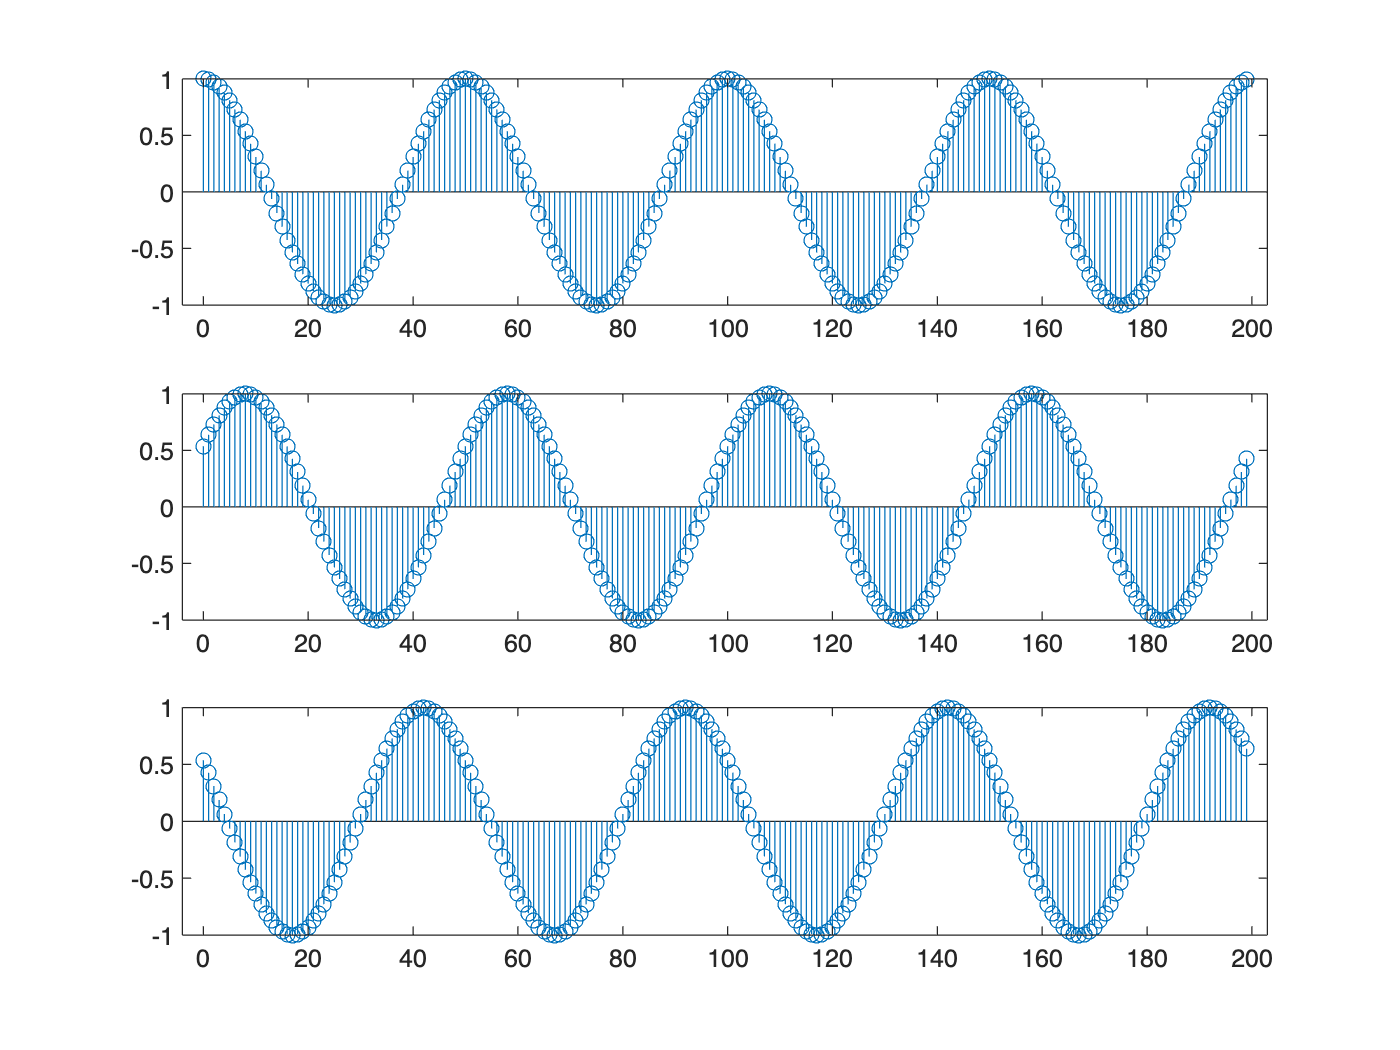

figure;
subplot(3,1,1);
stem(x, signal);

f = 200;

nf = -8;
signal_nf_m8 = A * cos(2 * pi * (f / fs) * (x + nf));
subplot(3,1,2);
stem(x, signal_nf_m8);
nf = 8;
signal_nf_8 = A * cos(2 * pi * (f / fs) * (x + nf));
subplot(3,1,3);
stem(x, signal_nf_8);

*Now change the amplitude of the cosine signal to 2 and plot in figure 22 the two cosine*

*signals with amplitude 1 and amplitude 2 (all other parameters the same for both)*

*How is the signal affected by changes in the amplitude?*

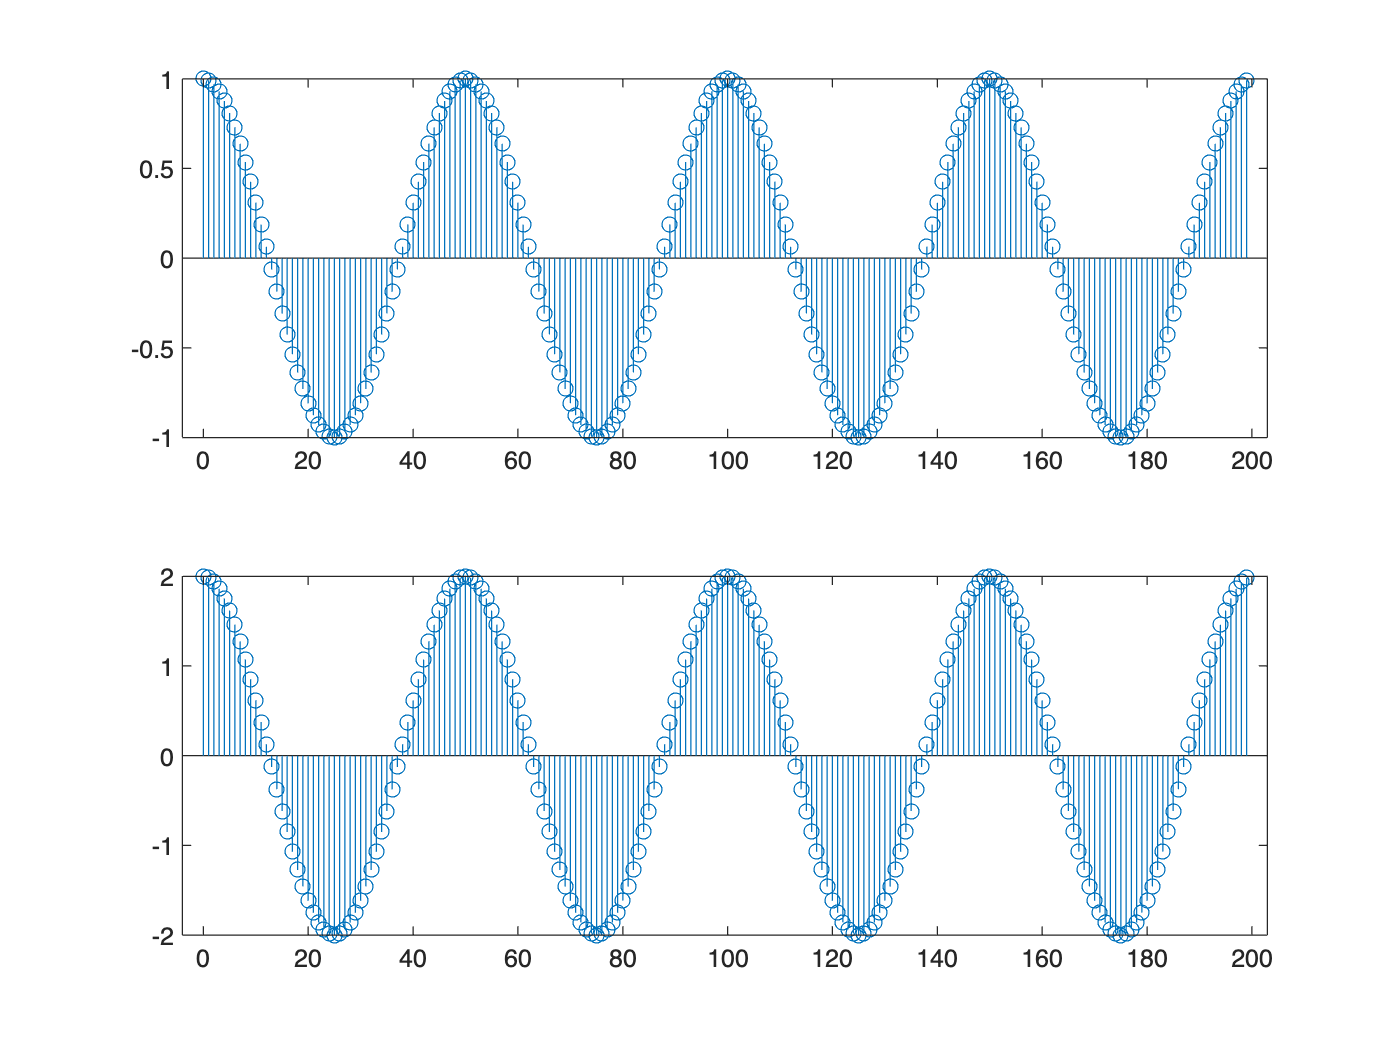

nf = 0;
A = 1;
figure;
subplot(2,1,1);
stem(x, signal);

A = 2;
signal_A2 = A * cos(2 * pi * (f / fs) * (x + nf));
subplot(2,1,2);
stem(x, signal_A2);

Listen to cosine signals with different amplitude and frequency.

Use the following code for this purpose (make sure that you have the audio volume on):

n = 0:5000;
Fs = 8192;
F1 = 500;
F2 = 1000;
A1 = 0.1
A2 = 1;
S1 = A1 * cos(2 * pi * (F1 / Fs) * n);
S2 = A2 * cos(2 * pi * (F1 / Fs) * n);
S3 = A1 * cos(2 * pi * (F2 / Fs) * n);
sound([S1 S2], Fs);
sound([S1 S3], Fs);

**Task 3:**

How can you compare if two signals are similar or different?

It can be made with the normalized scalar product (correlation).

The scalar product of two signals is calculated by:

1) Element-wise multiplication of the values of the two signals, and then

2) sum of these products.

To normalize the scalar product to the range [-1,1], the result of the above operation is divided

by the norm (length) of the two input signals.

Signal1 = [1 -1 1 -1 1 -1];
Signal2 = [-1 1 -1 1 -1 1];

Product = Signal1 .* Signal2;
SkalarProduct = sum(Product);
SkalarProduct

SkalarProduct = -6

Norm1 = norm(Signal1);
Norm2 = norm(Signal2);
NormSkalarProduct = SkalarProduct / Norm1 / Norm2;
NormSkalarProduct

NormSkalarProduct = -1.0000

*Verify manually the values obtained in Produkter and SkalProd*

*Calculate manually the scalar product of "Signal1 with itself" and check the result with*

*Matlab.*

*How do you interpret the values of the normalized scalar products that you obtain in each*

*case? Which value of the normalized scalar product corresponds to “the most similar”*

*signals, and which to the “the most different” signals?*

Product = Signal1 .* Signal1;
SkalarProduct = sum(Product);
NormSkalarProduct = SkalarProduct / Norm1 / Norm1;
NormSkalarProduct

NormSkalarProduct = 1.0000